3D Representation of Potential Field for Gauntlet

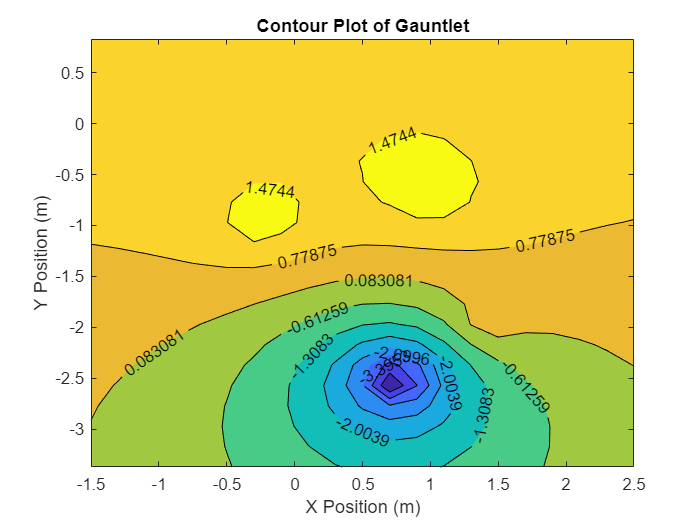

clf; hold off;
% Builds a mesh
[x,y]=meshgrid(-1.5:0.2:2.5, -3.37:0.2:1);
% Equation
v = - 0.5*log(sqrt((x-1.0).^2 + (y+0.7).^2)) - 0.5*log(sqrt((x+0.25).^2 + (y+1.0).^2))  - 0.5*log(sqrt((x-1.41).^2 + (y+2).^2)) + 2*log(sqrt((x-0.75).^2 + (y+2.5).^2));
% Plots contours with levels marked
contourf(x,y,v, 10, 'k','ShowText','On')
% Plots labels
title('Contour Plot of Gauntlet')
xlabel('X Position (m)')
ylabel('Y Position (m)')

legend('off')

Quiver Plot of Gradient of Potential Field

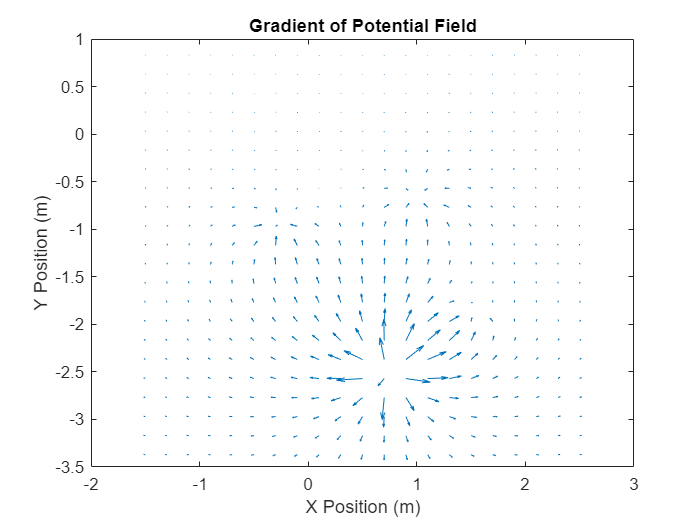

clf; hold off;
[x,y]=meshgrid(-1.5:0.2:2.5, -3.37:0.2:1);
% Defines the components of the gradient
[fx, fy] = gradient(v);
% Draws the arrows at the mesh points
quiver(x,y,fx,fy);
% Plot labels
title('Gradient of Potential Field')
xlabel('X Position (m)')
ylabel('Y Position (m)')

Gauntlet Objects Mapped Out w LIDAR

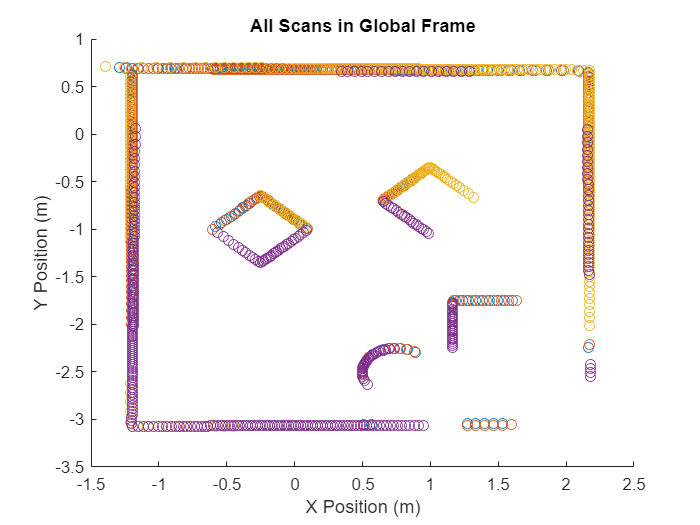

load('scandata.mat','r_all','theta_all');

% The origin of the Neato frame in the Global frame.
% Each row corresponds to the origin for a particular scan
origins = [0 0; 0 0; 1 0; 0 -2];

% the orientation of the Neato relative to the Global frame in radians.
% A positive angle here means the Neato's ihat_N axis was rotated
% counterclockwise from the ihat_G axis.
orientations = [0 pi/6 0 pi/3];

% the origin of the Lidar frame in the Neato frame (ihat_N, jhat_N).
origin_of_lidar_frame = [-0.084 0];

allScansFig = figure;

% for each scan
for i = 1 : size(origins,1)
    cartesianPointsInLFrame = [cos(theta_all(:,i)).*r_all(:,i)...
                               sin(theta_all(:,i)).*r_all(:,i)]';
    %figure;
    %scatter(cartesianPointsInLFrame(1,:), cartesianPointsInLFrame(2,:));
    %title(['Scan ', num2str(i), ' in Lidar frame']);
    
    % add a row of all ones so we can use translation matrices
    cartesianPointsInLFrame(end+1,:) = 1;
    cartesianPointsInNFrame = [1 0 origin_of_lidar_frame(1);...
                               0 1 origin_of_lidar_frame(2);...
                               0 0 1]*cartesianPointsInLFrame;
    %figure;
    %scatter(cartesianPointsInNFrame(1,:), cartesianPointsInNFrame(2,:));
    %title(['Scan ', num2str(i), ' in Neato frame']);
    
    % undo the rotation of the Neato so the points are with respected to
    % the global coordinate axes with the origin located at the Neato's
    % position
    rotatedPoints = [cos(orientations(i)) -sin(orientations(i)) 0;...
                     sin(orientations(i)) cos(orientations(i)) 0;...
                     0 0 1]*cartesianPointsInNFrame;
    %figure;
    %scatter(rotatedPoints(1,:), rotatedPoints(2,:));
    %title(['Scan ', num2str(i), ' in Global frame pre-translation']);

    % translate the points to be relative to the Global origin
    cartesianPointsInGFrame = [1 0 origins(i,1);...
                               0 1 origins(i,2);...
                               0 0 1]*rotatedPoints;

    % plot using the all scans figure
    figure(allScansFig);
    scatter(cartesianPointsInGFrame(1,:), cartesianPointsInGFrame(2,:));
    hold on;
    title('All Scans in Global Frame');      
    xlabel('X Position (m)')
    ylabel('Y Position (m)')
end

% display the figure that contains all of the scans
figure(allScansFig);

Hypothetical Gradient Descent to BoB Path

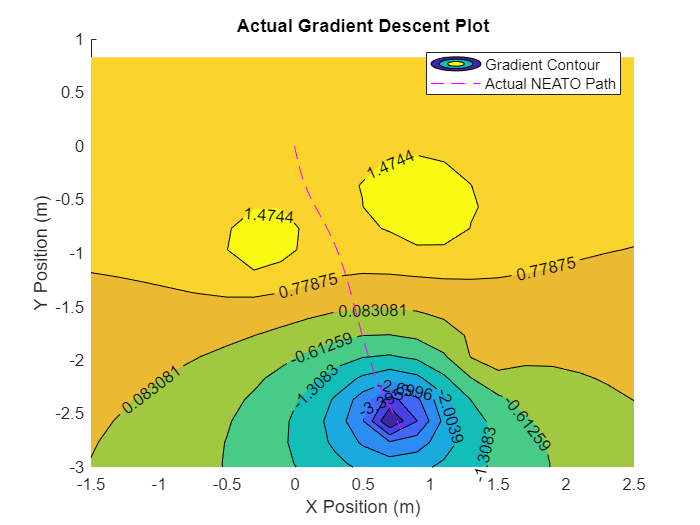

clf; hold on;

% Plots gradient descent contour
contourf(x,y,v, 10, 'k','ShowText','On')

% Function to navigate f(x, y) & gradient f(x, y)

% Set script parameter values (robot wheel base, angular speed, linear
% speed, gradient ascent parameters like lambda)
d = 0.235;
omega = 0.2;
speed = 0.75;
lambda = 0.01;

% Coordinate parameters
syms x1 y1;

% Equation containing objects
f = - 2*log(sqrt((x1-1.0).^2 + (y1+0.7).^2)) - 2*log(sqrt((x1+0.25).^2 + (y1+1.0).^2))  - 2*log(sqrt((x1-1.41).^2 + (y1+2).^2)) + 15*log(sqrt((x1-0.75).^2 + (y1+2.5).^2));

% Gradeint descent
g = -gradient(f, [x1, y1]);

% Initialize robot position & heading
position = [0; 0];
heading = [1; 0];

x_list = [0];
y_list = [0];

% While loop; computes angle to turn the robot to align it to the gradient
% Turns the robot
% Drives the robot forwards by lambda * sqrt(gradient^2)
% Checks if close enough to stop
stop = false;
time = 0;
while ~stop
    currentGradient = double(subs(g, {x1, y1}, {position(1), position(2)}));
    crossP = cross([heading; 0], [currentGradient; 0]);
    turnTheta = asin(norm(crossP)/(norm(heading)*norm(currentGradient)));
    turnTime = double(turnTheta)/omega;
    V_L = -sign(crossP(3))*omega*d/2;
    V_R = sign(crossP(3))*omega*d/2;
    
    start = time;
    while time-start < turnTime
        time = time + 0.01;
    end

    heading = currentGradient;
    
    forward = norm(currentGradient*lambda);
    forwardTime = forward/speed;

    start = time;
    while time-start < forwardTime
        time = time + 0.01;
    end
    
    position = position + currentGradient*lambda;
    x_list(end+1) = position(1);
    y_list(end+1) = position(2);
    
    stop = (forward < 0.01);
end
p = plot(x_list(1:42), y_list(1:42), 'm--');
axis([-1.5 2.5 -3 1]);
xlabel("X Position (m)")
ylabel("Y Position (m)")
title('Actual Gradient Descent Plot')
legend('Gradient Contour', 'Actual NEATO Path');

Actual NEATO Path Plot & Theoretical Gradient Descent Plot Layered Over Contour

clf; hold on;
% Plots gradient descent contour
contourf(x,y,v, 10, 'k','ShowText','On');

d = 0.235;
V_left_actual = diff(encoderLeftmeters)./diff(timeseconds);
V_right_actual = diff(encoderRightmeters)./diff(timeseconds);

speed_actual = (V_left_actual + V_right_actual)./2;
omega_actual = (V_right_actual - V_left_actual)./d;
r_actual = zeros(length(timeseconds), 2);
theta_actual = zeros(length(timeseconds), 1);
theta_actual(1) = 0;
r_actual(1, 1) = 0;
r_actual(1, 2) = 0;
dist = 0;


for n = 1:length(timeseconds)-1
    r_actual(n+1, 1) = r_actual(n,1) + speed_actual(n) * cos(theta_actual(n)) * (timeseconds(n+1) - timeseconds(n));
    r_actual(n+1, 2) = r_actual(n,2) + speed_actual(n) * sin(theta_actual(n)) * (timeseconds(n+1) - timeseconds(n));
    theta_actual(n+1) = theta_actual(n) + omega_actual(n)*(timeseconds(n+1) - timeseconds(n));
    dist = dist + sqrt((r_actual(n+1, 1)-r_actual(n, 1))^2 + (r_actual(n+1, 2)-r_actual(n, 2))^2);
end

dist

dist = 2.6977

time = timeseconds(end)-timeseconds(1)

time = 19.3000

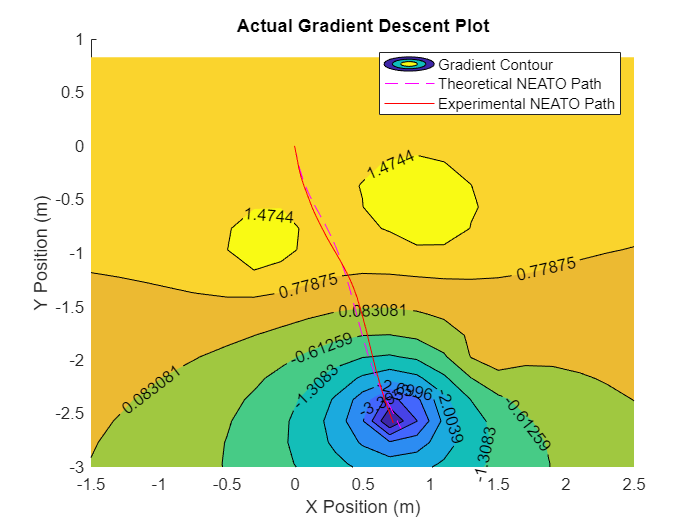

axis([-1.5 2.5 -3 1]);

p = plot(x_list(1:42), y_list(1:42), 'm--');
p2 = plot(r_actual(:,1), r_actual(:,2), 'r-');

xlabel("X Position (m)")
ylabel("Y Position (m)")
title('Actual Gradient Descent Plot')
legend('Gradient Contour', 'Theoretical NEATO Path', 'Experimental NEATO Path')

Actual NEATO Path Plot & Theoretical Gradient Descent Plot Layer Over LIDAR Scan & Contour Plot.


experimentaldeliverable = figure;
hold on;
% Plots gradient descent contour
figure(experimentaldeliverable)
contourf(x,y,v, 10, 'k','ShowText','On');

% for each scan
for i = 1 : size(origins,1)
    cartesianPointsInLFrame = [cos(theta_all(:,i)).*r_all(:,i)...
                               sin(theta_all(:,i)).*r_all(:,i)]';
    %figure;
    %scatter(cartesianPointsInLFrame(1,:), cartesianPointsInLFrame(2,:));
    %title(['Scan ', num2str(i), ' in Lidar frame']);
    
    % add a row of all ones so we can use translation matrices
    cartesianPointsInLFrame(end+1,:) = 1;
    cartesianPointsInNFrame = [1 0 origin_of_lidar_frame(1);...
                               0 1 origin_of_lidar_frame(2);...
                               0 0 1]*cartesianPointsInLFrame;
    %figure;
    %scatter(cartesianPointsInNFrame(1,:), cartesianPointsInNFrame(2,:));
    %title(['Scan ', num2str(i), ' in Neato frame']);
    
    % undo the rotation of the Neato so the points are with respected to
    % the global coordinate axes with the origin located at the Neato's
    % position
    rotatedPoints = [cos(orientations(i)) -sin(orientations(i)) 0;...
                     sin(orientations(i)) cos(orientations(i)) 0;...
                     0 0 1]*cartesianPointsInNFrame;
    %figure;
    %scatter(rotatedPoints(1,:), rotatedPoints(2,:));
    %title(['Scan ', num2str(i), ' in Global frame pre-translation']);

    % translate the points to be relative to the Global origin
    cartesianPointsInGFrame = [1 0 origins(i,1);...
                               0 1 origins(i,2);...
                               0 0 1]*rotatedPoints;

    % plot using the all scans figure
    figure(experimentaldeliverable);
    scatter(cartesianPointsInGFrame(1,:), cartesianPointsInGFrame(2,:), 'HandleVisibility','off');
    hold on;
    title('All Scans in Global Frame');      
    xlabel('X Position (m)')
    ylabel('Y Position (m)')
end

d = 0.235;
V_left_actual = diff(encoderLeftmeters)./diff(timeseconds);
V_right_actual = diff(encoderRightmeters)./diff(timeseconds);

speed_actual = (V_left_actual + V_right_actual)./2;
omega_actual = (V_right_actual - V_left_actual)./d;
r_actual = zeros(length(timeseconds), 2);
theta_actual = zeros(length(timeseconds), 1);
theta_actual(1) = 0;
r_actual(1, 1) = 0;
r_actual(1, 2) = 0;
dist = 0;


for n = 1:length(timeseconds)-1
    r_actual(n+1, 1) = r_actual(n,1) + speed_actual(n) * cos(theta_actual(n)) * (timeseconds(n+1) - timeseconds(n));
    r_actual(n+1, 2) = r_actual(n,2) + speed_actual(n) * sin(theta_actual(n)) * (timeseconds(n+1) - timeseconds(n));
    theta_actual(n+1) = theta_actual(n) + omega_actual(n)*(timeseconds(n+1) - timeseconds(n));
    dist = dist + sqrt((r_actual(n+1, 1)-r_actual(n, 1))^2 + (r_actual(n+1, 2)-r_actual(n, 2))^2);
end

dist

dist = 2.6977

time = timeseconds(end)-timeseconds(1)

time = 19.3000

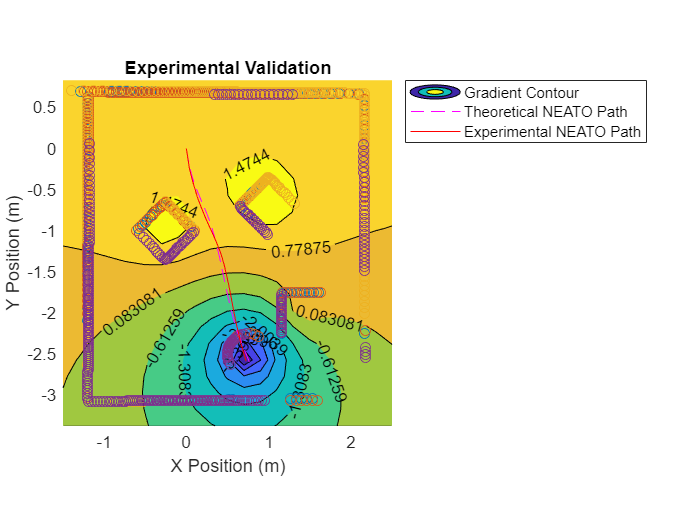

axis([-1.5 2.5 -3 1]);

figure(experimentaldeliverable)
p = plot(x_list(1:42), y_list(1:42), 'm--');
figure(experimentaldeliverable)
p2 = plot(r_actual(:,1), r_actual(:,2), 'r-');

xlabel("X Position (m)")
ylabel("Y Position (m)")
title('Experimental Validation')
legend('Gradient Contour', 'Theoretical NEATO Path', 'Experimental NEATO Path', 'Location', 'northeastoutside')
axis equal